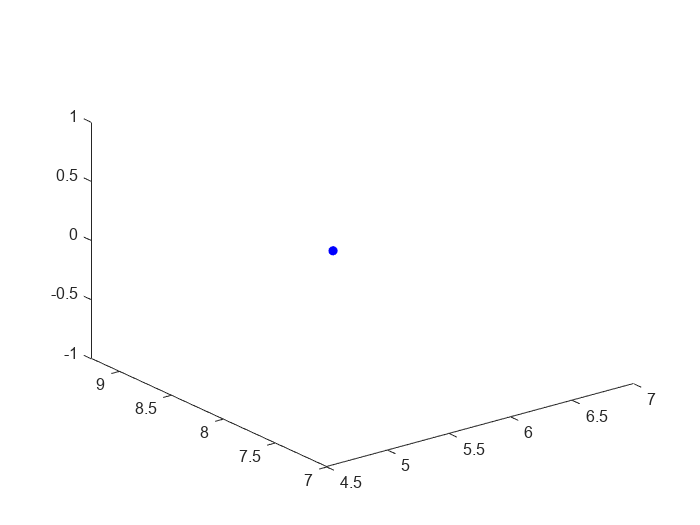

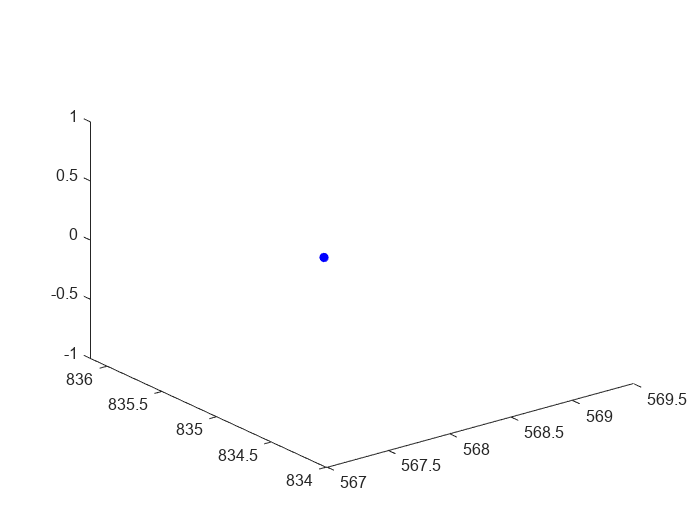

% Define the initial position, altitude, speed, and direction of the aircraft
initial_position = [0, 0, 0];
altitude_profile = 1000;
speed_profile = 100;
direction_profile = 0;
% Define the radar outputs in radians
azimuth_radians = 1.5;
elevation_radians = 0.5;
range_meters = 100;
% Convert the radar outputs to degrees
azimuth_degrees = rad2deg(azimuth_radians);
elevation_degrees = rad2deg(elevation_radians);

% Convert the altitude, speed, and direction to Cartesian coordinates
[x, y, z] = sph2cart(altitude_profile, direction_profile, speed_profile);

% Define the time step and the total time for the simulation
time_step = 0.1;
total_time = 10;

% Initialize the position of the aircraft
position = initial_position;

% Create a figure and axis for plotting
fig = figure;
ax = axes('Parent', fig);

% Set the axis labels and title
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title('3D View of Aircraft Scenario with Radar Scanning');

% Loop through the simulation time
for t = 0:time_step:total_time
    % Update the position of the aircraft based on its speed and direction
    position = position + [x, y, z] * time_step;
    
    % Update the position of the aircraft in the plot
    plot3(position(1), position(2), position(3), 'bo-', 'MarkerSize', 5, 'MarkerFaceColor', 'b');
    
    % Pause the loop for a short period to allow the plot to update
    pause(0.1);
end

function degrees = rad2deg(radians)
    degrees = radians * (180 / pi);
end
function radians = deg2rad(degrees)
    radians = degrees * (pi / 180);
end


